# Advection Diffusion Reaction Equation in 1D with non-homogeneous Dirichlet boundary conditions.

The following differential problem is given;

$\left\lbrace\begin{array}{cc}
 -(\mu u')' + \beta u' + \sigma u = f  \quad  x \in (0,2) 
\\
 u(0) = a
\\
 u(2) = b
\end{array}
$ ,     

with $\mu(x) = 1 + x, \quad \beta(x) = -3x, \quad \sigma(x) = e^{-x}$, $f = 1$, $a = -3$, $b = 4$.

We want to find an approximation of $u(1)$.  We consider a uniform mesh size $h = \left(\frac{1}{2}\right)^{l}, \quad l = 1, \dots, 7$: in this way, the point $x = 1$ always belongs to the mesh. The chosen strategy is to reduce this non-homogeneous problem in an homogeneous problem and then apply the same method showed in "Homogeneous_Dirichelt_boundary_problem" file.

The functions $\tilde{u}(x) := \left(\frac{b - a}{2}\right)x + a$, with $\tilde{u}(0) = a$, $\tilde{u}(2) = b$ and$w(x) := u(x) - \tilde{u}(x)$ are defined:  the last one is the solution of the homogeneous problem with the known term$\tilde{f} = 1 + \frac{1}{2}(b - a) + \frac{3}{2}x(b - a) - e^{-x} \left( \frac{1}{2}(b - a)x + a \right)$. 

If we call  $w_h$ the discretized solution of the new problem,  $w_h$((length($u_h$) + 1) / 2 ) contains the approximate value of $u(1)$ (by summing it with $\tilde{u}(1)$).

So, we calculate the value of the approximate solution in $x = 1$, $u_h$ = $w_h$((length($w_h$) + 1) / 2 ) + $\tilde{u}(1)$, with different mesh sizes $h$.

c = 0;
d = 2;
l = 1:8;
h_2 = (1/2).^(l);
H = length(h_2);

format long
a = -3;
b = 4;

mu_x = @(x) 1 + x;
beta_x = @(x) -3*x;
sigma_x = @(x) exp(-x);

u_tilde = @(x) (0.5*(b - a).*x) + a;

f_tilde = @(x) 1 + 0.5*(b - a) + 3.*x.*(b - a)*0.5 - exp(-x).*(a + 0.5*(b - a).*x);

approximate_value = ones(H,1);


- I solve the discretized problem for each $h$.

for i = 1:H

    L = 2*(1/h_2(i)) - 1; 
    known_term = ones(L,1);
    points = linspace(c,d, 2*(1/h_2(i)) + 1); 
    
    u_h = zeros(L,1); 

    valued_u_tilde = zeros(L,1);
   
    diagD = zeros(L,1);
     
    % k = j
    for m = 1:L
        diagD(m,1) = (1/h_2(i))*(0.5*(mu_x(points(m)) + mu_x(points(m + 1))) + 0.5*(mu_x(points(m + 1)) + mu_x(points(m + 2))));
    end

    codiaginfD = zeros(L - 1, 1);
    
    % k = j - 1
    for m = 2:L
        codiaginfD(m - 1,1) = -(1/h_2(i))*(0.5*(mu_x(points(m)) + mu_x(points(m + 1))));
    end

    codiagsupD = zeros(L - 1, 1);

    % k = j + 1
     for m = 1:(L - 1)
        codiagsupD(m,1) = -(1/h_2(i))*(0.5*(mu_x(points(m + 1)) + mu_x(points(m + 2))));
     end

    D2 = diag(diagD) + diag(codiagsupD, 1) + diag(codiaginfD, -1);

    diagC = zeros(L, 1);

    % k = j
     for m = 1:L
         diagC(m,1) = (1/2)*(0.5*(beta_x(points(m)) + beta_x(points(m + 1))) - 0.5*(beta_x(points(m + 1)) + beta_x(points(m + 2))));
     end

    codiaginfC = zeros(L - 1, 1);
    
    % k = j - 1
     for m = 2:L
         codiaginfC(m-1,1) = -(1/2)*(0.5*(beta_x(points(m)) + beta_x(points(m + 1))));
     end

    codiagsupC = zeros(L - 1, 1);

    % k = j + 1
     for m = 1:(L - 1)
        codiagsupC(m,1) = (1/2)*(0.5*(beta_x(points(m + 1)) + beta_x(points(m + 2))));
     end

     C2 = diag(diagC) + diag(codiagsupC, 1) + diag(codiaginfC, -1);

     diagR = zeros(L, 1);

    % k = j
     for m = 1:L
         diagR(m,1) = (1/3)*(h_2(i))*(0.5*(sigma_x(points(m)) + sigma_x(points(m + 1))) + 0.5*(sigma_x(points(m + 1)) + sigma_x(points(m + 2))));
     end

    codiaginfR = zeros(L - 1, 1);
    
    % k = j - 1
     for m = 2:L
         codiaginfR(m-1,1) = (1/6)*(h_2(i))*(0.5*(sigma_x(points(m)) + sigma_x(points(m + 1))));
     end

    codiagsupR = zeros(L - 1, 1);

    % k = j + 1
     for m = 1:(L - 1)
         codiagsupR(m,1) = (1/6)*(h_2(i))*(0.5*(sigma_x(points(m + 1)) + sigma_x(points(m + 2))));
     end

    R2 = diag(diagR) + diag(codiagsupR, 1) + diag(codiaginfR, -1);
     
    A2 = D2 + C2 + R2;
    
    for k= 1:L
        known_term(k) = f_tilde(points(k + 1));
        valued_u_tilde(k, 1) = u_tilde(points(k + 1));
    end
    
    known_term = h_2(i)*known_term;

    w_h = A2\known_term;
    
    u_h = w_h + valued_u_tilde; 

    approximate_value(i,1) = u_h((length(u_h) + 1)/2);
    
end

approximate_value

approximate_value =     3.0707
    3.0788
    3.0812
    3.0819
    3.0820
    3.0821
    3.0821
    3.0821


I calculate the difference between the values of the approximate solution in $x = 1$ obtained in two consecutive iterations.

difference = ones(length(approximate_value) - 1, 1);
for i = 1:(length(approximate_value) - 1)
    difference(i) = abs(approximate_value(i + 1) - approximate_value(i));
end

difference

difference =     0.0081
    0.0024
    0.0006
    0.0002
    0.0000
    0.0000
    0.0000


- The value $u_{h}(1)$ (in the sense that it is the value of the approximate solution in $x = 1$) seems to be already "stable" from the first iterations: the difference between the first two values is near to $10^{-3}$ and it rapidly decreases for the following ones.

For $h = \left(\frac{1}{2}\right)^{8}$: $u_{h}(1)$ =  3.082099.

- Finally, the plot of the approximate solution.

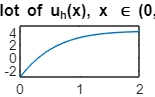

 plot_points = ones(length(points) - 2, 1);

         for p = 1:length(plot_points)
             plot_points(p) = points(p + 1);
         end

         plot(plot_points, u_h);
         title('Plot of u_{h}(x), x \in (0,2)')